# Example 7.1-7.4: Direction Finding with an Adcock Antenna

Nicholas O'Donoughue 1 July 2019

*Consider the detection of the transmitter in Table 7.1a with an Adcock antenna system, as described in Table 7.1b. If the true AOA is *$$\theta=10^\circ$$*, and the Adcock antenna is steered to three angles for testing, *$$-15^\circ$$*, *$$0^\circ$$*, and *$$15^\circ$$*, and dwells at each angle for *$$T=10\ \mu s$$*, at what range will the angle estimation error (RMSE) be *$$\sigma_\theta = 1^\circ$$*?*

## Solution

First, we define the parameters.

Pt = 35e-3; % W
Gt = 34; % dBi
B_s_MHz = 31.3; % MHz
B_s = B_s_MHz * 1e6;
f0_GHz = 35; % GHz
f0 = f0_GHz * 1e9; % Hz
lambda = utils.constants.c/f0; % m
Lt = 0; % dB
ht = 500; % m -- unused
Lr = 2; % dB
F_n = 4; % dB
B_n_MHz = 40; % MHz
B_n = B_n_MHz * 1e6; % Hz
T_s = 10e-6; % s
hr = 500; % m

th_true = 10; % True signal DOA (deg)
psi_true = th_true*pi/180;

We begin by computing the SNR. Note that the SNR referenced above in the performance calculations is that of an omnidirectional antenna; the gain from the Adcock antenna is accounted for in the `g` and `g_dot` terms. For simplicity, we assume free space path loss, regardless of standoff distance.

% Compute the SNR, as a function of range
R_min_km =  1; % km
R_max_km =  100; % km
R_step_km = 1; % km
R = (R_min_km:R_step_km:R_max_km)*1e3; % m
S = (10*log10(Pt) + Gt - Lt) + 20*log10(lambda./(4*pi*R)) - Lr;
N = 10*log10(utils.constants.boltzmann*utils.constants.T0*B_n)+F_n;
snr_db = S-N;

### Example 7.1 - Adcock and Beampattern-based DF

Next, we determine how many samples are taken at each steering angle, based on the noise bandwidth of the receiver $B_n$, and length $T_s$ of each collection

% Compute the number of time samples available
M = 1 + floor(T_s*B_n);

This results in M=400.  Finally, we compute the gain vectors, utilizing the provided function, and note that the returned gain vectors are function handles that accept the difference between the steering and gain vectors, in radians.

% Generate the gain functions
[g,g_dot] = aoa.make_gain_functions('Adcock',.25,0);
th_steer = [-15,0,15];
psi_steer = th_steer*pi/180;

All that remains is to evaluate the CRLB.Conversion from the CRLB of $$\psi$$ to the RMSE of $$\theta$$ is computed via square root and radian to degree conversion.

% Compute the CRLB
crlb_psi = aoa.directional_crlb(snr_db,M,g,g_dot,psi_steer,psi_true);
rmse_th_adcock = (180/pi)*sqrt(crlb_psi);

% Re-do for directional
D_lam = 5;
[g,g_dot] = aoa.make_gain_functions('Rectangular',D_lam,0);
crlb_psi_rect = aoa.directional_crlb(snr_db,M,g,g_dot,psi_steer,psi_true);
rmse_th_rect = (180/pi)*sqrt(crlb_psi_rect);

Figure 7.14 plots the RMSE in units of degrees, as a function of the distance between transmitter and receiver, assuming free space path loss (along with several other receivers defined in later example problems). From this example, we can see that the Adcock antenna DF achieves $$\sigma_\theta \leq 1^\circ$$ at a standoff range of roughly 1.6 km. As in Chapter 3, this problem could easily be inverted, to compute the acceptable standoff range for a required SINR directly, rather than via searching the figure. This is left as an exercise for the reader.

Results are also plotted in Figure 7.14 for a rectangular aperture with $$D=5\lambda$$ and the same sample points $$\psi_i$$. In this case, the DF system achieves $$\sigma_\theta\leq 1^\circ$$ at $$R \leq 10$$ km. However, this result is not robust. Recall that, for $$D=5\lambda$$, the beamwidth of the rectangular aperture is $$\approx 11.5^\circ$$. Since the beamwidth is less than the spacing between sample points, the signal return could fall into a null between two of the sampled angles. To properly use such a directional aperture, the angular space should be sampled more densely.

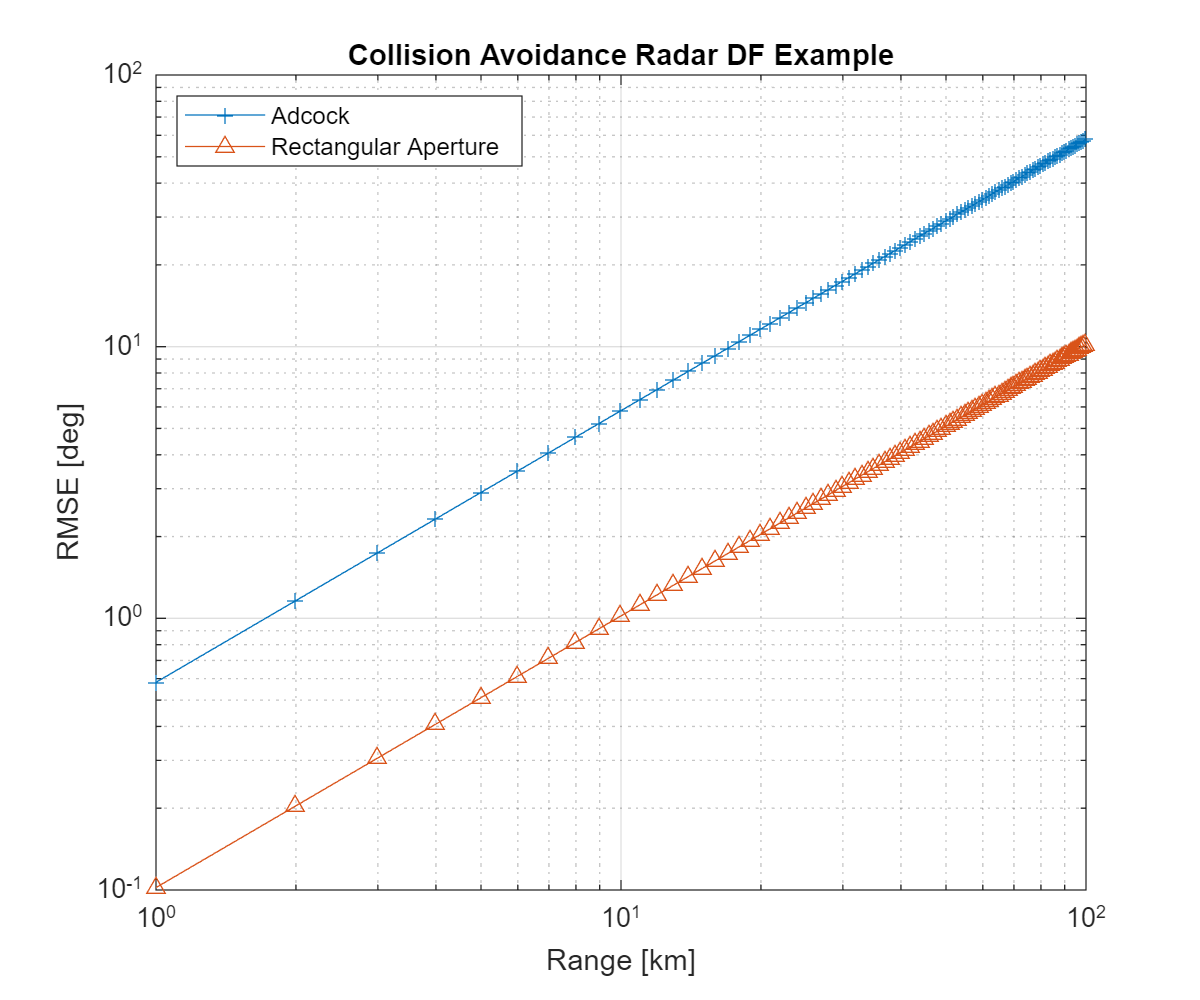

% Plot
figure;
loglog(R/1e3,rmse_th_adcock,'-+','DisplayName','Adcock');
hold on;
loglog(R/1e3,rmse_th_rect,'-^','DisplayName','Rectangular Aperture');
xlabel('Range [km]');
ylabel('RMSE [deg]');
title('Collision Avoidance Radar DF Example');
ylim([.1 100]);
grid on;
legend('Location','NorthWest');

### Example 7.2: Watson-Watt DF

*Repeat Example 7.1, but with a Watson-Watt receiver instead of a single Adcock antenna pair. At what range does the angle estimation error reach *$$1^\circ$$*?*

The calculations for $$\xi$$ and M are unchanged. In this case, the CRLB can then be plotted directly from $$\xi$$ and M.

% Watson Watt
crlb_psi_watson = aoa.watson_watt_crlb(snr_db,M);
rmse_th_watson = (180/pi)*sqrt(crlb_psi_watson);

The results are plotted for this example in Figure 7.14. The desired accuracy of $$1^\circ$$ is achieved with a Watson-Watt receiver when $$R \leq 3$$ km. This is better than the single-channel Adcock antenna, but not as accurate as the high-gain rectangular aperture. Of course, the benefit of the Watson-Watt receiver is that there is instantaneous coverage at all azimuth angles, whereas the others must be scanned mechanically to scan the area of regard.

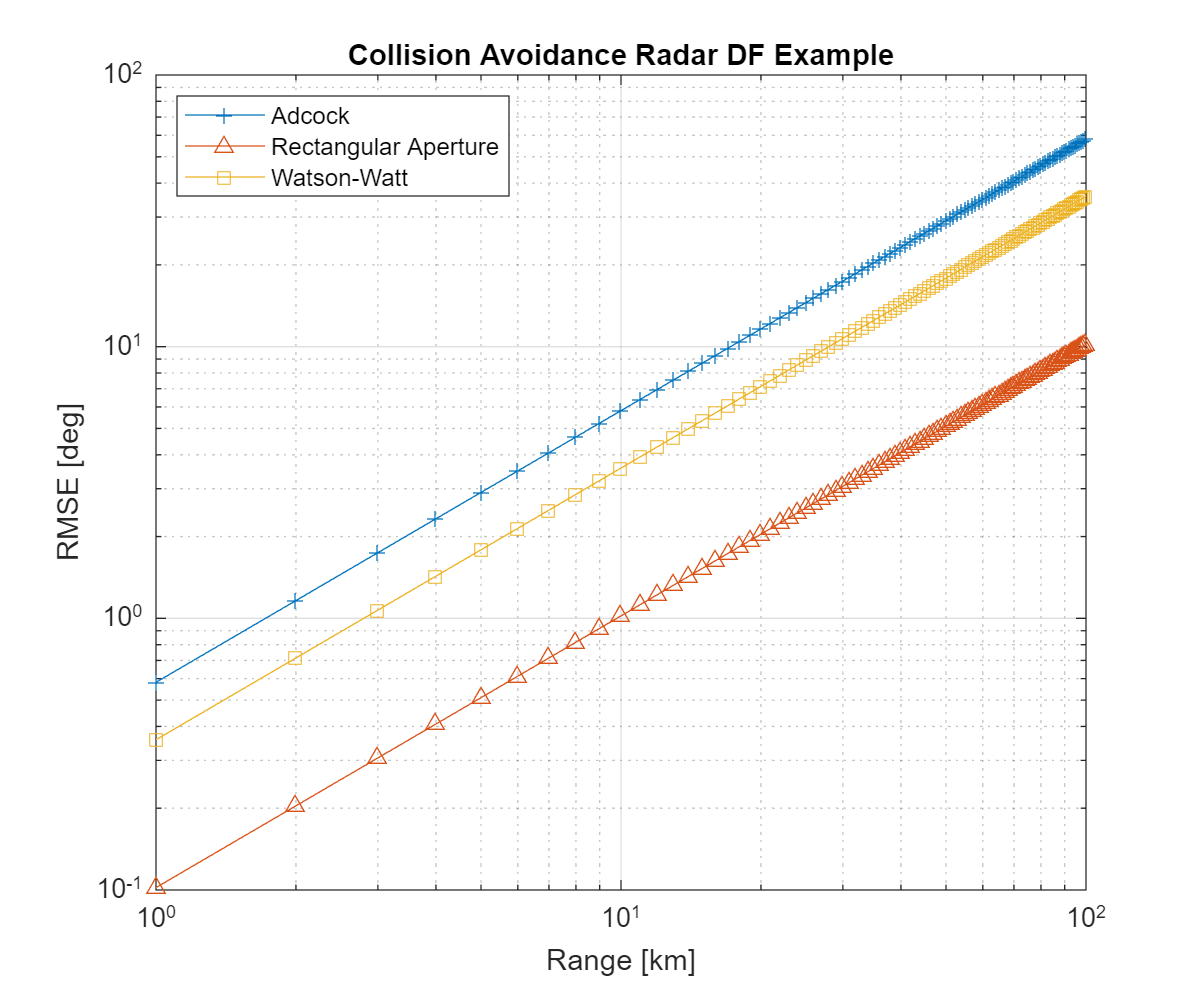

% Plot
figure;
loglog(R/1e3,rmse_th_adcock,'-+','DisplayName','Adcock');
hold on;
loglog(R/1e3,rmse_th_rect,'-^','DisplayName','Rectangular Aperture');
xlabel('Range [km]');
ylabel('RMSE [deg]');
title('Collision Avoidance Radar DF Example');
ylim([.1 100]);
grid on;
legend('Location','NorthWest');

loglog(R/1e3,rmse_th_watson,'-s','DisplayName','Watson-Watt');

### Example 7.3: Doppler-based DF

Repeat Example 7.2, but with a Doppler receiver with a radius of $$\lambda/2$$, and timed to execute a single rotation over the course of a single pulse. At what range does the angle estimation error reach $$1^\circ$$?

We begin with the SNR vector computed before, and define the parameters necessary for calculation of the CRLB.

% Doppler Model
ts = 1/(2*f0);
R_dop = lambda/2;
fr = 1/T_s;
crlb_psi_dop = aoa.doppler_crlb(snr_db,M,1,ts,f0,R_dop,fr,psi_true);
rmse_th_dop = (180/pi)*sqrt(crlb_psi_dop);

This can be plotted and searched to find the point where `rmse_th_doppler` is equal to $$1^\circ$$. Unfortunately, due to the complexity of the CRLB, it can't be easily computed analytically. The results, along with the prior examples, are plotted in Figure 7.14, and the answer is that the Doppler DF system, as specified, achieves $$1^\circ$$ accuracy when $$R \leq 1$$ km.

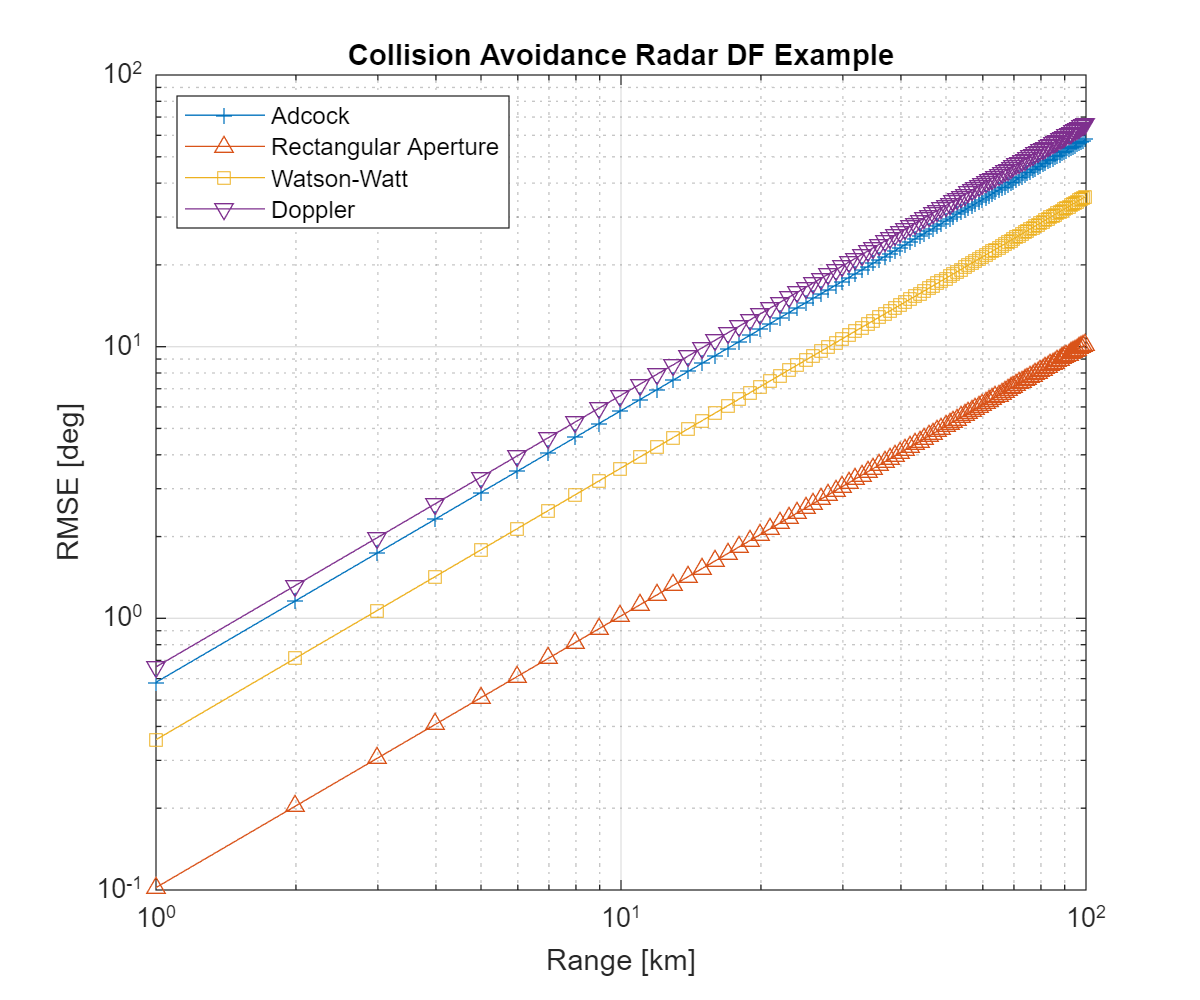

% Plot
figure;
loglog(R/1e3,rmse_th_adcock,'-+','DisplayName','Adcock');
hold on;
loglog(R/1e3,rmse_th_rect,'-^','DisplayName','Rectangular Aperture');
xlabel('Range [km]');
ylabel('RMSE [deg]');
title('Collision Avoidance Radar DF Example');
ylim([.1 100]);
grid on;
legend('Location','NorthWest');

loglog(R/1e3,rmse_th_watson,'-s','DisplayName','Watson-Watt');
loglog(R/1e3,rmse_th_dop,'-v','DisplayName','Doppler');

### Example 7.4: Interferometer DF

*Repeat Example 7.3, but with a two-channel interferometer, with a spacing of *$$d=\lambda/2$$*. Assume that *$$\alpha=1$$*, and therefore that both receivers have the same SNR (*$$\xi_{\mathrm{eff}}=.5\xi_1=.5\xi_2$$*). At what range does the angle estimation error reach *$$1^\circ$$*?  What about if *$$d=2\lambda$$*?*

To begin, we invert the CRLB equation and compute the required SNR.

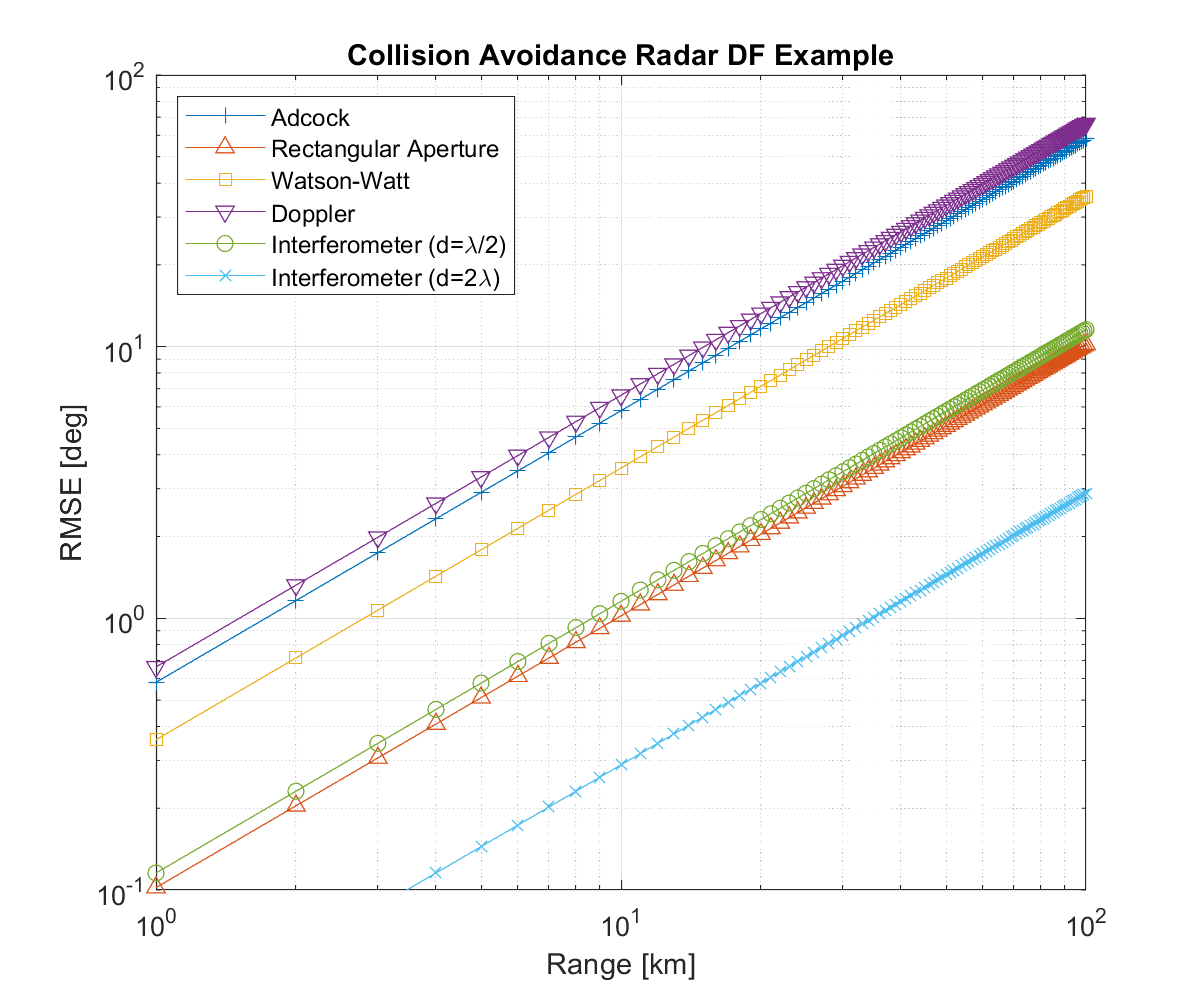

% Compute RMSE
d_lam_narrow = .5; % wavelengths
crlb_psi_interf = aoa.interf_crlb(snr_db,snr_db,M,d_lam_narrow,psi_true);
rmse_th_interf_narrow = (180/pi)*sqrt(crlb_psi_interf);

d_lam_wide = 2;   % wavelengths
crlb_psi_interf = aoa.interf_crlb(snr_db,snr_db,M,d_lam_wide,psi_true);
rmse_th_interf_wide = (180/pi)*sqrt(crlb_psi_interf);

% Plot
figure;
loglog(R/1e3,rmse_th_adcock,'-+','DisplayName','Adcock');
hold on;
loglog(R/1e3,rmse_th_rect,'-^','DisplayName','Rectangular Aperture');
xlabel('Range [km]');
ylabel('RMSE [deg]');
title('Collision Avoidance Radar DF Example');
ylim([.1 100]);
grid on;
legend('Location','NorthWest');

loglog(R/1e3,rmse_th_watson,'-s','DisplayName','Watson-Watt');
loglog(R/1e3,rmse_th_dop,'-v','DisplayName','Doppler');

loglog(R/1e3,rmse_th_interf_narrow,'-o','DisplayName','Interferometer (d=\lambda/2)');
loglog(R/1e3,rmse_th_interf_wide,'-x','DisplayName','Interferometer (d=2\lambda)');